# Alexnet-like, HRTF-dependent

Paweł Antoniuk 2021

Bialystok University of Technology

clear; clc;
rng('default');
inputSize = [349, 150, 4];
inputSpecgramsFile = 'Spectrograms/specgrams-all-lin-150.h5';

Training params

params.InputSpecgramsFile = inputSpecgramsFile;
params.MaxEpochs = 30;
params.InitialLearnRate = 0.005;
params.MiniBatchSize = 128;

Evaluation loop params

splitStart = 1;
splitStop = 7;

Preview data

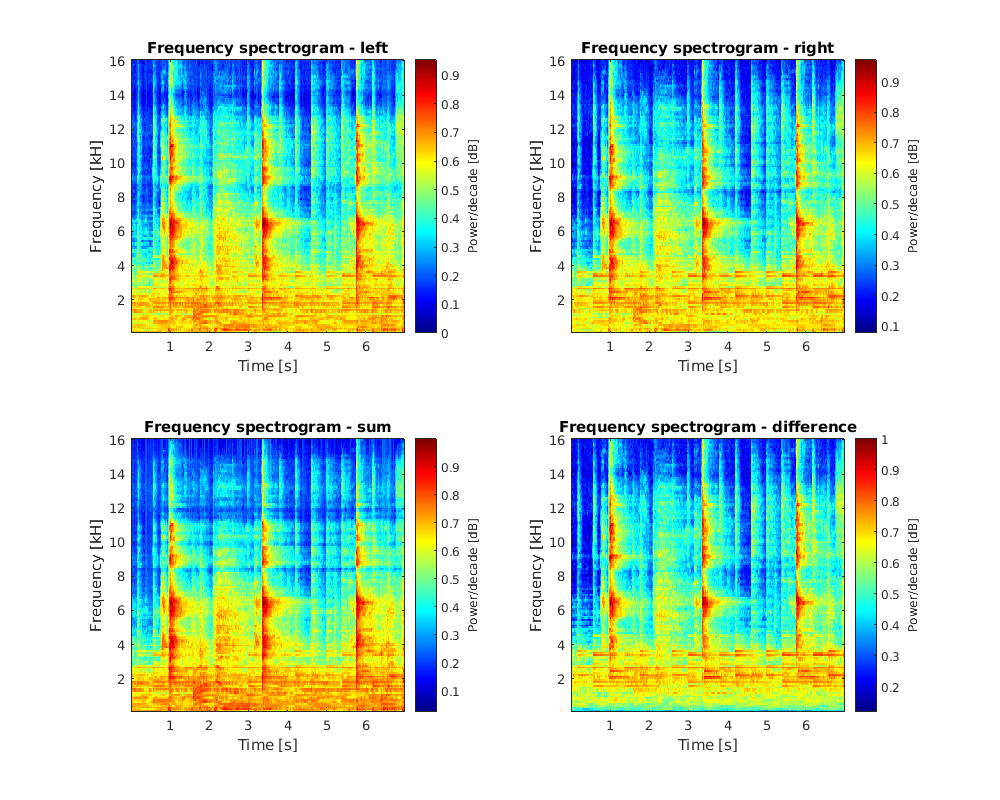

indxSpecgram = 1;
sampleSpecgrams = h5read(inputSpecgramsFile, '/data', ...
    [1, 1, 1, indxSpecgram], [inputSize, 1]);
timeValues = h5read(inputSpecgramsFile, '/axis/time');
freqValues = h5read(inputSpecgramsFile, '/axis/freq');

specNames = {'left', 'right', 'sum', 'difference'};

clf
figure('Position', [0 0 1000 800])
for ii = 1:4
    subplot(2, 2, ii);
    imagesc(timeValues, freqValues / 1000, sampleSpecgrams(:, :, ii)'); 
    colormap jet; 
    axis xy;  
    pbaspect([1 1 1])
    title(['Frequency spectrogram - ', specNames{ii}])
    xlabel('Time [s]')
    ylabel('Frequency [kH]')
    ylabel(colorbar, 'Power/decade [dB]')
end

## Model training

rng('default');

Load dataset and metdata

dsFilenames = h5read(params.InputSpecgramsFile, '/filenames');
[songNames, HRTFs, HRTFGroups] = getSongNamesHRTFsGroups(dsFilenames);
uniqueHRTFNames = unique(HRTFs);
uniqueHRTFGroupNames = unique(HRTFGroups);
ds = H5MatrixDatastore(params.InputSpecgramsFile, '/data', '/labels');

Split dataset into training and test dataset by song names in 'train recordings.csv' and 'test recordings.csv'

nSplits = splitStop - splitStart + 1;
splitsResults = cell(1, nSplits);
for iSplit = splitStart:splitStop
iSplit
splitTic = tic;

Select only a subset of training and test data. Selection is made for each HRTF group name (aachen, mti, etc.) so training dataset contains all HRTF group names except the specific one and test data contains only the specified HRTF group name.

### Data preparation

Splits are predefinied in the csv files

trainRecordings = readtable('train recordings.csv', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');
testRecordings = readtable('test recordings.csv', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');

currentTrainingRecordings = trainRecordings{:, iSplit};
currentTestRecordings = testRecordings{:, iSplit};

trainDs = ds.filterDs(@(ii) any(strcmp(songNames(ii), currentTrainingRecordings)));
testDs = ds.filterDs(@(ii) any(strcmp(songNames(ii), currentTestRecordings))); 

### Checking

Check if trainDs + valDs and testDs have distinct song names (empty arrays excepted)

assert(numel(intersect(unique(dsFilenames(trainDs.IndexValues)), unique(dsFilenames(testDs.IndexValues)))) == 0);
assert(numel(intersect(unique(songNames(trainDs.IndexValues)), unique(songNames(testDs.IndexValues)))) == 0);

Load layers

layers = [
    imageInputLayer(inputSize,"Name","imageinput", 'Normalization',"none")
    convolution2dLayer([3 3],16,"Name","conv_1")
    reluLayer("Name","relu_1")
    batchNormalizationLayer("Name","batchnorm_1")
    
    maxPooling2dLayer([3 2],"Name","maxpool_1","Stride",[3 2])
    
    convolution2dLayer([3 3],32,"Name","conv_2")
    reluLayer("Name","relu_2")
    batchNormalizationLayer("Name","batchnorm_2")
    
    maxPooling2dLayer([3 2],"Name","maxpool_2","Stride",[3 2])
    
    convolution2dLayer([3 3],64,"Name","conv_3")
    reluLayer("Name","relu_3")
    batchNormalizationLayer("Name","batchnorm_3")
    
    maxPooling2dLayer([2 2],"Name","maxpool_3","Stride",[2 2])
    
    convolution2dLayer([3 3],128,"Name","conv_4")
    reluLayer("Name","relu_4")
    batchNormalizationLayer("Name","batchnorm_4")
    
    maxPooling2dLayer([2 2],"Name","maxpool_4","Stride",[2 2])
    
    convolution2dLayer([3 3],128,"Name","conv_5")
    reluLayer("Name","relu_5")    
    batchNormalizationLayer("Name","batchnorm_5")
    
    dropoutLayer(0.5,"Name","dropout_1")
    fullyConnectedLayer(64,"Name","fc_1")
    reluLayer("Name","relu_6")    
    
    dropoutLayer(0.5,"Name","dropout_2")
    fullyConnectedLayer(32,"Name","fc_2")
    reluLayer("Name","relu_7")    
    
    dropoutLayer(0.5,"Name","dropout_3")
    fullyConnectedLayer(16,"Name","fc_3")
    reluLayer("Name","relu_8")    
    
    dropoutLayer(0.5,"Name","dropout_4")
    fullyConnectedLayer(2,"Name","fc_4")
    softmaxLayer('Name', 'softmax')
    
    classificationLayer('Name', 'output')];

Training options

options = trainingOptions('adam', ...
    'MaxEpochs', params.MaxEpochs, ...
    'InitialLearnRate', params.InitialLearnRate, ...
    'MiniBatchSize', params.MiniBatchSize, ...
    'Shuffle', 'every-epoch', ...
    'VerboseFrequency', 1000, ...
    'ValidationFrequency', 50, ...
    'LearnRateSchedule', 'piecewise', ...
	'LearnRateDropPeriod', 5, ...
	'LearnRateDropFactor', 0.5, ...
    'ExecutionEnvironment','multi-gpu', ...
    'ValidationData', testDs);

%     'Plots',"training-progress", ...

Training loop

[net, info] = trainNetwork(trainDs, layers, options);
% nLearnableParams = countLearnableParams(net)

### Evaulate performance

HRTFGroupsResults = containers.Map();
for iHRTFGroup = 1:length(uniqueHRTFGroupNames)
currentSelectedHRTFGroup = uniqueHRTFGroupNames{iHRTFGroup}
% restHRTFGroups = setdiff(uniqueHRTFGroupNames, currentSelectedHRTFGroup);
currentHRTFGroupTestDs = testDs.filterDs(@(ii) any(strcmp(HRTFGroups(ii), currentSelectedHRTFGroup)));

Evaluate performacne on the training set

preds = classify(net, trainDs);
targets = trainDs.Labels(trainDs.IndexValues);
trainAccuracy = nnz(preds == targets) / length(trainDs.IndexValues)

Evaluate performance on the test set

preds = classify(net, currentHRTFGroupTestDs);
targets = currentHRTFGroupTestDs.Labels(currentHRTFGroupTestDs.IndexValues);
testAccuracy = nnz(preds == targets) / length(currentHRTFGroupTestDs.IndexValues)

Save the HRTF group results

results.net = net;
results.info = info;
results.trainAccuracy = trainAccuracy;
results.testAccuracy = testAccuracy;
HRTFGroupsResults(currentSelectedHRTFGroup) = results;

Save the split results

outputFilename = sprintf('lmpa2d_partial_results/partial_results_inhrtf %s', datestr(clock, 'HHMMSS'));
save(outputFilename, '-v7.3')

end % end % for iHRTFGroup
splitsResults{iSplit} = HRTFGroupsResults;

outputFilename = sprintf('lmpa2d_partial_results/partial_results_insplit %s', datestr(clock, 'HHMMSS'));
save(outputFilename, '-v7.3')

toc(splitTic)
end % end % for iSplit 

iSplit =      1


Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:17 |       50.78% |       54.10% |       2.0704 |       0.7162 |          0.0050 |
|       1 |          50 |       00:00:39 |       55.47% |       64.22% |       0.6930 |       0.6797 |          0.0050 |
|       1 |         100 |       00:01:00 |       62.50% |       69.36% |       0.6674 |       0.6584 |          0.0050 |
|       2 |         150 |       00:

currentSelectedHRTFGroup = 'aachen'

trainAccuracy =    0.999879343629344


testAccuracy =    0.993750000000000


currentSelectedHRTFGroup = 'ari'

trainAccuracy =    0.999879343629344


testAccuracy =    0.998214285714286


currentSelectedHRTFGroup = 'cipic'

trainAccuracy =    0.999879343629344


testAccuracy =    0.987500000000000


currentSelectedHRTFGroup = 'clubfritz'

trainAccuracy =    0.999879343629344


testAccuracy =      1


currentSelectedHRTFGroup = 'hutubs'

trainAccuracy =    0.999879343629344


testAccuracy =    0.989285714285714


currentSelectedHRTFGroup = 'listen'

trainAccuracy =    0.999879343629344


testAccuracy =    0.998214285714286


currentSelectedHRTFGroup = 'mit'

trainAccuracy =    0.999879343629344


testAccuracy =    0.993750000000000


currentSelectedHRTFGroup = 'riec'

trainAccuracy =    0.999879343629344


testAccuracy =    0.996428571428571


currentSelectedHRTFGroup = 'sadie'

trainAccuracy =    0.999879343629344


testAccuracy =    0.994642857142857


currentSelectedHRTFGroup = 'scut'

trainAccuracy =    0.999879343629344


testAccuracy =      1


currentSelectedHRTFGroup = 'th-koln'

trainAccuracy =    0.999879343629344


testAccuracy =    0.998214285714286


currentSelectedHRTFGroup = 'tu-berlin'

trainAccuracy =    0.999879343629344


testAccuracy =    0.992500000000000


currentSelectedHRTFGroup = 'viking'

trainAccuracy =    0.999879343629344


testAccuracy =    0.998214285714286


Elapsed time is 2023.791103 seconds.


iSplit =      2


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:13 |       49.22% |       46.33% |       1.8921 |       0.7602 |          0.0050 |
|       1 |          50 |       00:00:33 |       52.34% |       50.37% |       0.6953 |       0.6916 |          0.0050 |
|       1 |         100 |       00:00:52 |       60.16% |       68.63% |       0.6524 |       0.6713 |          0.0050 |
|       2 |         150 |       00:01:12 |       73.44% |       82.96% |       0.6000 |       0.4537 |          0.0050 |
|       2 |         200 |       

currentSelectedHRTFGroup = 'aachen'

trainAccuracy =    0.999939671814672


testAccuracy =    0.981250000000000


currentSelectedHRTFGroup = 'ari'

trainAccuracy =    0.999939671814672


testAccuracy =    0.989285714285714


currentSelectedHRTFGroup = 'cipic'

trainAccuracy =    0.999939671814672


testAccuracy =    0.967857142857143


currentSelectedHRTFGroup = 'clubfritz'

trainAccuracy =    0.999939671814672


testAccuracy =    0.985714285714286


currentSelectedHRTFGroup = 'hutubs'

trainAccuracy =    0.999939671814672


testAccuracy =    0.976785714285714


currentSelectedHRTFGroup = 'listen'

trainAccuracy =    0.999939671814672


testAccuracy =    0.985714285714286


currentSelectedHRTFGroup = 'mit'

trainAccuracy =    0.999939671814672


testAccuracy =    0.987500000000000


currentSelectedHRTFGroup = 'riec'

trainAccuracy =    0.999939671814672


testAccuracy =    0.980357142857143


currentSelectedHRTFGroup = 'sadie'

trainAccuracy =    0.999939671814672


testAccuracy =    0.992857142857143


currentSelectedHRTFGroup = 'scut'

trainAccuracy =    0.999939671814672


testAccuracy =    0.981250000000000


currentSelectedHRTFGroup = 'th-koln'

trainAccuracy =    0.999939671814672


testAccuracy =    0.992857142857143


currentSelectedHRTFGroup = 'tu-berlin'

trainAccuracy =    0.999939671814672


testAccuracy =    0.965000000000000


currentSelectedHRTFGroup = 'viking'

trainAccuracy =    0.999939671814672


testAccuracy =    0.971428571428571


Elapsed time is 2071.753987 seconds.


iSplit =      3


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |       44.53% |       54.21% |       1.8584 |       0.7036 |          0.0050 |
|       1 |          50 |       00:00:35 |       56.25% |       64.48% |       0.7366 |       0.6860 |          0.0050 |
|       1 |         100 |       00:00:56 |       61.72% |       73.53% |       0.6581 |       0.6196 |          0.0050 |
|       2 |         150 |       00:01:16 |       78.12% |       85.44% |       0.4189 |       0.3697 |          0.0050 |
|       2 |         200 |       

currentSelectedHRTFGroup = 'aachen'

trainAccuracy =    0.999879343629344


testAccuracy =    0.981250000000000


currentSelectedHRTFGroup = 'ari'

trainAccuracy =    0.999879343629344


testAccuracy =    0.994642857142857


currentSelectedHRTFGroup = 'cipic'

trainAccuracy =    0.999879343629344


testAccuracy =    0.971428571428571


currentSelectedHRTFGroup = 'clubfritz'

trainAccuracy =    0.999879343629344


testAccuracy =    0.992857142857143


currentSelectedHRTFGroup = 'hutubs'

trainAccuracy =    0.999879343629344


testAccuracy =    0.989285714285714


currentSelectedHRTFGroup = 'listen'

trainAccuracy =    0.999879343629344


testAccuracy =    0.982142857142857


currentSelectedHRTFGroup = 'mit'

trainAccuracy =    0.999879343629344


testAccuracy =    0.987500000000000


currentSelectedHRTFGroup = 'riec'

trainAccuracy =    0.999879343629344


testAccuracy =    0.982142857142857


currentSelectedHRTFGroup = 'sadie'

trainAccuracy =    0.999879343629344


testAccuracy =    0.989285714285714


currentSelectedHRTFGroup = 'scut'

trainAccuracy =    0.999879343629344


testAccuracy =    0.993750000000000


currentSelectedHRTFGroup = 'th-koln'

trainAccuracy =    0.999879343629344


testAccuracy =    0.998214285714286


currentSelectedHRTFGroup = 'tu-berlin'

trainAccuracy =    0.999879343629344


testAccuracy =    0.975000000000000


currentSelectedHRTFGroup = 'viking'

trainAccuracy =    0.999879343629344


testAccuracy =    0.975000000000000


Elapsed time is 2150.096349 seconds.


iSplit =      4


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |       46.88% |       50.00% |       1.5875 |       0.8352 |          0.0050 |
|       1 |          50 |       00:00:35 |       50.00% |       50.52% |       0.7226 |       0.6906 |          0.0050 |
|       1 |         100 |       00:00:56 |       56.25% |       56.01% |       0.6879 |       0.6924 |          0.0050 |
|       2 |         150 |       00:01:17 |       56.25% |       66.08% |       0.6792 |       0.6726 |          0.0050 |
|       2 |         200 |       

currentSelectedHRTFGroup = 'aachen'

trainAccuracy =      1


testAccuracy =    0.981250000000000


currentSelectedHRTFGroup = 'ari'

trainAccuracy =      1


testAccuracy =    0.982142857142857


currentSelectedHRTFGroup = 'cipic'

trainAccuracy =      1


testAccuracy =    0.964285714285714


currentSelectedHRTFGroup = 'clubfritz'

trainAccuracy =      1


testAccuracy =    0.996428571428571


currentSelectedHRTFGroup = 'hutubs'

trainAccuracy =      1


testAccuracy =    0.978571428571429


currentSelectedHRTFGroup = 'listen'

trainAccuracy =      1


testAccuracy =    0.991071428571429


currentSelectedHRTFGroup = 'mit'

trainAccuracy =      1


testAccuracy =    0.962500000000000


currentSelectedHRTFGroup = 'riec'

trainAccuracy =      1


testAccuracy =    0.978571428571429


currentSelectedHRTFGroup = 'sadie'

trainAccuracy =      1


testAccuracy =    0.989285714285714


currentSelectedHRTFGroup = 'scut'

trainAccuracy =      1


testAccuracy =    0.968750000000000


currentSelectedHRTFGroup = 'th-koln'

trainAccuracy =      1


testAccuracy =    0.983928571428571


currentSelectedHRTFGroup = 'tu-berlin'

trainAccuracy =      1


testAccuracy =    0.985000000000000


currentSelectedHRTFGroup = 'viking'

trainAccuracy =      1


testAccuracy =    0.962500000000000


Elapsed time is 2146.351225 seconds.


iSplit =      5


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |       46.88% |       59.12% |       1.8843 |       0.6783 |          0.0050 |
|       1 |          50 |       00:00:35 |       57.03% |       65.90% |       0.6650 |       0.6483 |          0.0050 |
|       1 |         100 |       00:00:56 |       71.09% |       85.78% |       0.5082 |       0.4059 |          0.0050 |
|       2 |         150 |       00:01:17 |       76.56% |       85.41% |       0.4709 |       0.3839 |          0.0050 |
|       2 |         200 |       

currentSelectedHRTFGroup = 'aachen'

trainAccuracy =    0.999879343629344


testAccuracy =    0.993750000000000


currentSelectedHRTFGroup = 'ari'

trainAccuracy =    0.999879343629344


testAccuracy =    0.994642857142857


currentSelectedHRTFGroup = 'cipic'

trainAccuracy =    0.999879343629344


testAccuracy =    0.975000000000000


currentSelectedHRTFGroup = 'clubfritz'

trainAccuracy =    0.999879343629344


testAccuracy =    0.996428571428571


currentSelectedHRTFGroup = 'hutubs'

trainAccuracy =    0.999879343629344


testAccuracy =    0.989285714285714


currentSelectedHRTFGroup = 'listen'

trainAccuracy =    0.999879343629344


testAccuracy =    0.983928571428571


currentSelectedHRTFGroup = 'mit'

trainAccuracy =    0.999879343629344


testAccuracy =    0.993750000000000


currentSelectedHRTFGroup = 'riec'

trainAccuracy =    0.999879343629344


testAccuracy =    0.987500000000000


currentSelectedHRTFGroup = 'sadie'

trainAccuracy =    0.999879343629344


testAccuracy =    0.987500000000000


currentSelectedHRTFGroup = 'scut'

trainAccuracy =    0.999879343629344


testAccuracy =    0.987500000000000


currentSelectedHRTFGroup = 'th-koln'

trainAccuracy =    0.999879343629344


testAccuracy =    0.991071428571429


currentSelectedHRTFGroup = 'tu-berlin'

trainAccuracy =    0.999879343629344


testAccuracy =    0.985000000000000


currentSelectedHRTFGroup = 'viking'

trainAccuracy =    0.999879343629344


testAccuracy =    0.976785714285714


Elapsed time is 2178.536797 seconds.


iSplit =      6


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |       48.44% |       57.03% |       1.2026 |       0.6779 |          0.0050 |
|       1 |          50 |       00:00:35 |       45.31% |       50.10% |       0.6904 |       0.6924 |          0.0050 |
|       1 |         100 |       00:00:56 |       58.59% |       66.93% |       0.6850 |       0.6891 |          0.0050 |
|       2 |         150 |       00:01:17 |       61.72% |       69.54% |       0.6346 |       0.6613 |          0.0050 |
|       2 |         200 |       

currentSelectedHRTFGroup = 'aachen'

trainAccuracy =    0.999939671814672


testAccuracy =      1


currentSelectedHRTFGroup = 'ari'

trainAccuracy =    0.999939671814672


testAccuracy =    0.998214285714286


currentSelectedHRTFGroup = 'cipic'

trainAccuracy =    0.999939671814672


testAccuracy =    0.987500000000000


currentSelectedHRTFGroup = 'clubfritz'

trainAccuracy =    0.999939671814672


testAccuracy =    0.998214285714286


currentSelectedHRTFGroup = 'hutubs'

trainAccuracy =    0.999939671814672


testAccuracy =    0.994642857142857


currentSelectedHRTFGroup = 'listen'

trainAccuracy =    0.999939671814672


testAccuracy =      1


currentSelectedHRTFGroup = 'mit'

trainAccuracy =    0.999939671814672


testAccuracy =    0.975000000000000


currentSelectedHRTFGroup = 'riec'

trainAccuracy =    0.999939671814672


testAccuracy =      1


currentSelectedHRTFGroup = 'sadie'

trainAccuracy =    0.999939671814672


testAccuracy =    0.996428571428571


currentSelectedHRTFGroup = 'scut'

trainAccuracy =    0.999939671814672


testAccuracy =    0.993750000000000


currentSelectedHRTFGroup = 'th-koln'

trainAccuracy =    0.999939671814672


testAccuracy =    0.992857142857143


currentSelectedHRTFGroup = 'tu-berlin'

trainAccuracy =    0.999939671814672


testAccuracy =    0.995000000000000


currentSelectedHRTFGroup = 'viking'

trainAccuracy =    0.999939671814672


testAccuracy =      1


Elapsed time is 2238.356554 seconds.


iSplit =      7


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |       49.22% |       53.43% |       1.7257 |       0.7107 |          0.0050 |
|       1 |          50 |       00:00:35 |       53.12% |       59.12% |       0.7145 |       0.6887 |          0.0050 |
|       1 |         100 |       00:00:56 |       71.88% |       78.89% |       0.5859 |       0.4982 |          0.0050 |
|       2 |         150 |       00:01:17 |       80.47% |       85.84% |       0.4735 |       0.3261 |          0.0050 |
|       2 |         200 |       

currentSelectedHRTFGroup = 'aachen'

trainAccuracy =      1


testAccuracy =    0.956250000000000


currentSelectedHRTFGroup = 'ari'

trainAccuracy =      1


testAccuracy =    0.980357142857143


currentSelectedHRTFGroup = 'cipic'

trainAccuracy =      1


testAccuracy =    0.987500000000000


currentSelectedHRTFGroup = 'clubfritz'

trainAccuracy =      1


testAccuracy =    0.964285714285714


currentSelectedHRTFGroup = 'hutubs'

trainAccuracy =      1


testAccuracy =    0.966071428571429


currentSelectedHRTFGroup = 'listen'

trainAccuracy =      1


testAccuracy =    0.966071428571429


currentSelectedHRTFGroup = 'mit'

trainAccuracy =      1


testAccuracy =    0.987500000000000


currentSelectedHRTFGroup = 'riec'

trainAccuracy =      1


testAccuracy =    0.958928571428571


currentSelectedHRTFGroup = 'sadie'

trainAccuracy =      1


testAccuracy =    0.980357142857143


currentSelectedHRTFGroup = 'scut'

trainAccuracy =      1


testAccuracy =    0.981250000000000


currentSelectedHRTFGroup = 'th-koln'

trainAccuracy =      1


testAccuracy =    0.989285714285714


currentSelectedHRTFGroup = 'tu-berlin'

trainAccuracy =      1


testAccuracy =    0.977500000000000


currentSelectedHRTFGroup = 'viking'

trainAccuracy =      1


testAccuracy =    0.964285714285714


Elapsed time is 2274.216540 seconds.


Save workspace

outputFilename = sprintf('lmpa2d_results/results %s', datestr(clock, 'HHMMSS'));
save(outputFilename, '-v7.3')

Save to xls

outputTable = table('Size', [length(uniqueHRTFGroupNames) 7], ...
    'VariableTypes', repmat({'double'}, 1, 7), ...
    'VariableNames', cellstr(num2str((0:6)')), ...
    'RowNames', uniqueHRTFGroupNames);
outputTable.Properties.DimensionNames{1} = ' ';

for iSplit = splitStart:splitStop
    HRTFGroupsResultsKeys = keys(splitsResults{iSplit});
    HRTFGroupsResultsValues = values(splitsResults{iSplit});
    
    for iHRTFGroup = 1:length(HRTFGroupsResultsKeys)
        outputTable{iHRTFGroup, iSplit} = HRTFGroupsResultsValues{iHRTFGroup}.testAccuracy;
    end
end

writetable(outputTable, [outputFilename '.xls'], ...
    'WriteVariableNames', true, ...
    'WriteRowNames',true);